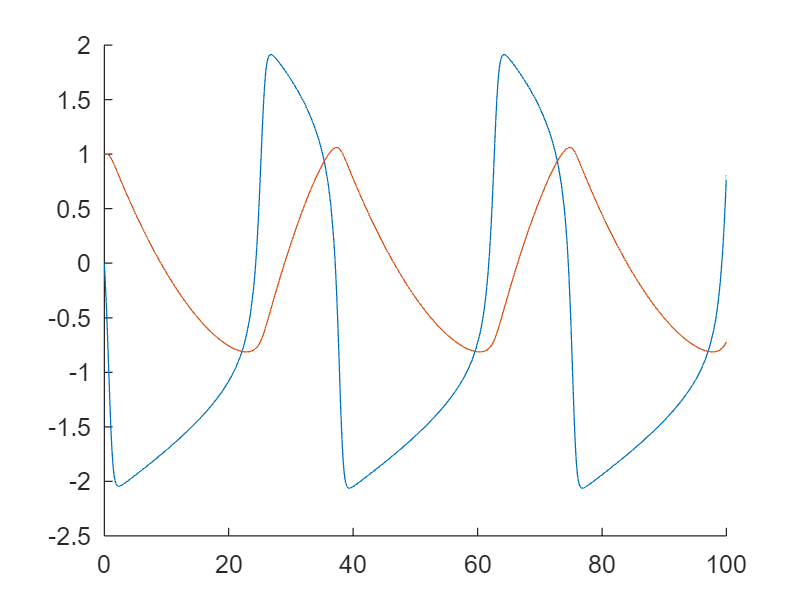

e = 0.08;
a = 0.5;
b = 0.2;

f1 = @(v,w) v - (1/3)*v^3 - w;

f2 = @(v,w) e*(v + a -b*w);

dxdt = @(t,x)[f1(x(1), x(2));
              f2(x(1), x(2))]; 

[T, X] = ode45(dxdt, [0,100], [0,1]);

figure; hold on;
plot(T, X(:,1))
plot(T, X(:,2))

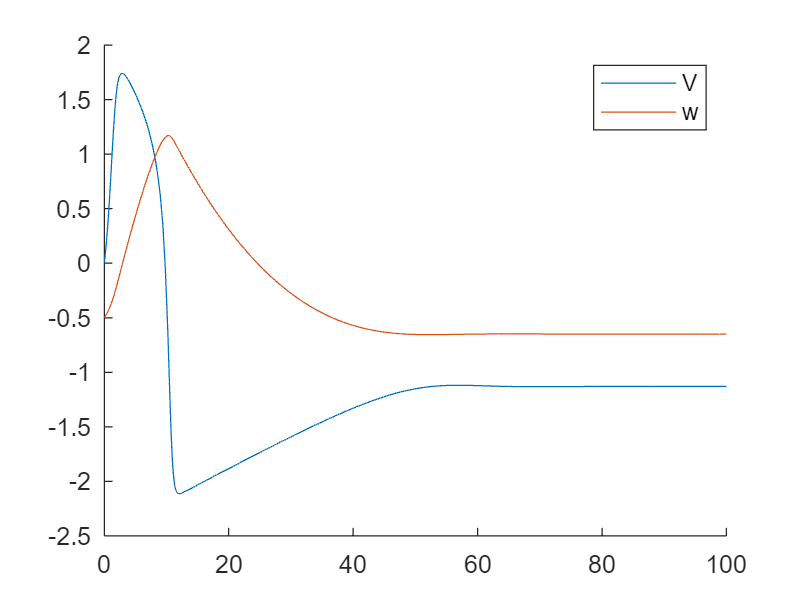

e = 0.08;
a = 1;
b = 0.2;

f1 = @(v,w) v - (1/3)*v^3 - w;

f2 = @(v,w) e*(v + a -b*w);

dxdt = @(t,x)[f1(x(1), x(2));
              f2(x(1), x(2))]; 

[T, X] = ode45(dxdt, [0,100], [-0,-0.5]);

figure; hold on;
plot(T, X(:,1))
plot(T, X(:,2))
legend('V','w')

%steady state is -0.649, -1.12981


%e = 0.08;
%a = 1;
%b = 0.2;
%i0 = 1.0;
%tstart = 40;
%tstop = 47;
%
%I = @(t) i0*(t>tstart).*(t<tstop);
%
%f1 = @(v,w) v - (1/3)*v^3 - w;
%
%f2 = @(v,w) e*(v + a -b*w);
%
%dxdt = @(t,x)[f1(x(1), x(2)) + I(t);
%              f2(x(1), x(2))]; 
%
%[T, X] = ode45(dxdt, [40,47], [ -1.12981,-0.649]);
%
%figure; hold on;
%plot(T, X(:,1))
%plot(T, X(:,2))
%legend('v','w')
%
%%V promotes w, w inhibits v, 
%% v inhbits v, w inhibts itself, dwdt is always much smaller than v
%% because of epsolon; fast positive, slow inhibition
%

%e = 0.08;
%a = 1;
%b = 0.2;
%i0 = 1.0;
%tstart = 40;
%tstop = 47;
%d = 0.9
%
%I = @(t) i0*(t>tstart).*(t<tstop);
%
%dvdt1 = @(v,w) v(1) - (1/3)*v(1)^3 - w(1) + d*(v(4) -2*v(1)+v(2));
%dwdt1 = @(v,w) e*(v(1) + a -b*w(1));
%
%dvdt2 = @(v,w) v(2) - (1/3)*v(2)^3 - w(2) + d*(v(1) -2*v(2)+v(3));
%dwdt2 = @(v,w) e*(v(2) + a -b*w(2));
%
%dvdt3 = @(v,w) v(3) - (1/3)*v(3)^3 - w(3) + d*(v(2) -2*v(3)+v(4));
%dwdt3 = @(v,w) e*(v(3) + a -b*w(3));
%
%dvdt4 = @(v,w) v(4) - (1/3)*v(4)^3 - w(4) + d*(v(4) -2*v(3)+v(1));
%dwdt4 = @(v,w) e*(v(4) + a -b*w(4));
%
%dxdt = @(t,x)[dvdt1(x(1), x(2)) + I(t);
%              dwdt1(x(1), x(2))
%              dvdt2(x(1), x(2)) + I(t);
%              dwdt2(x(1), x(2)); 
%              dvdt3(x(1), x(2)) + I(t);
%              dwdt3(x(1), x(2));
%              dvdt4(x(1), x(2)) + I(t);
%              dwdt4(x(1), x(2))];
%
%[T, X] = ode45(dxdt, [40,47], [ -1.12981,-0.649]);
%
%figure; hold on;
%plot(T, X(:,1))
%plot(T, X(:,2))
%

d = 0.9

d = 0.9000

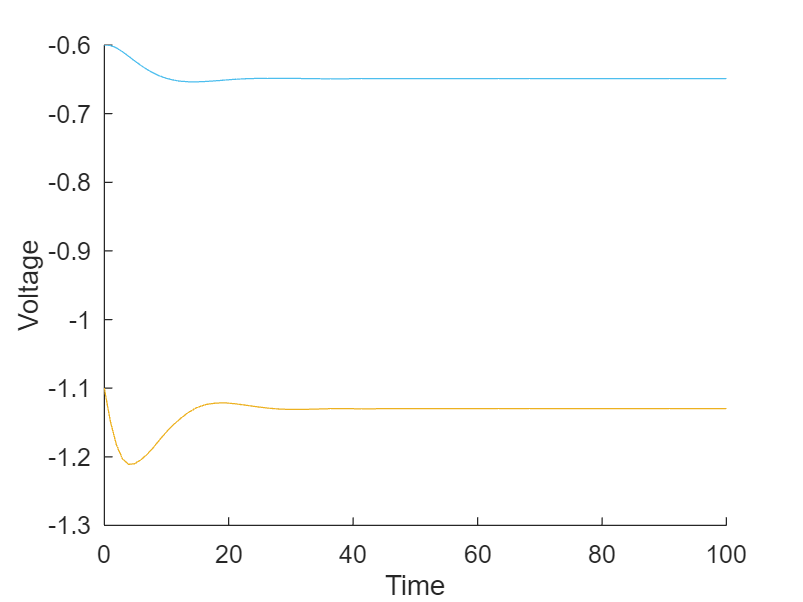

e = 0.08;
a = 1;
b = 0.2;
i0 = 1.0;
tstart = 40;
tstop = 47;

I = @(t) i0*(t>tstart).*(t<tstop);

f1 = @(v,w) v - (1/3)*v.^3 - w;

f2 = @(v,w) e*(v + a -b*w);

dxdt = @(t,x)[f1(x(1:10), x(11:20))+d*([x(2:10); x(1)] - 2*x(1:10) + [x(10); x(1:9)]);
              f2(x(1:10), x(11:20))];


ic = [-1.1*ones(10,1);-0.6*ones(10,1)];

[T, X] = ode45(dxdt, [0,100], ic);

figure(4); clf; hold on;
plot(T,X(:,1:10));
plot(T,X(:,11:20))
xlabel('Time');
ylabel('Voltage')

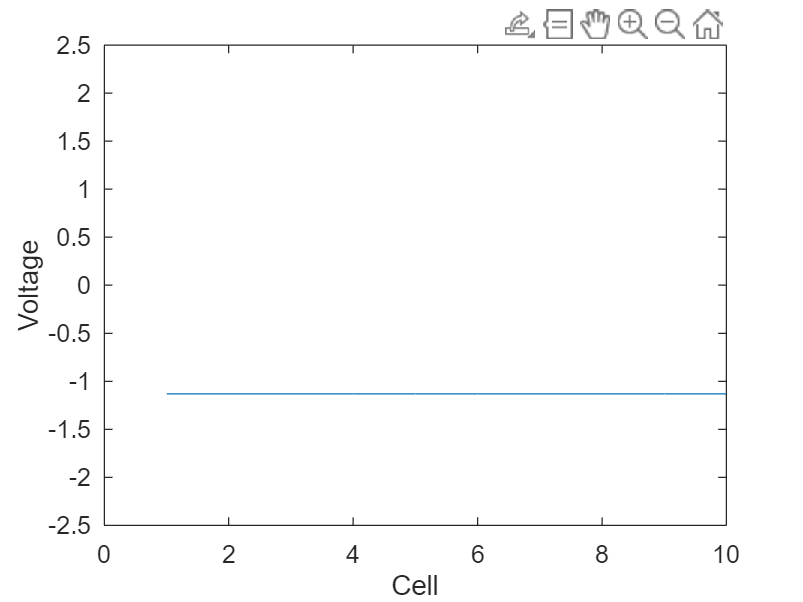


figure(5)
% movie
for nt=1:numel(T)
    figure(5); clf; hold on; box on;
    plot(X(nt,1:10)); 
    set(gca,'ylim', [-2.5,2.5])
    xlabel('Cell');
    ylabel('Voltage')
    drawnow;
end

d = 0.9

d = 0.9000

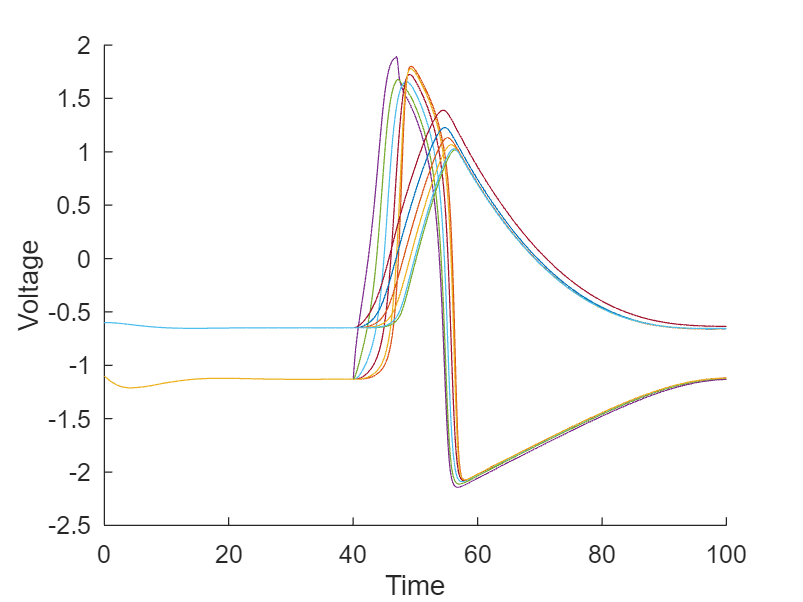

e = 0.08;
a = 1;
b = 0.2;
i0 = 1.0;
tstart = 40;
tstop = 47;

I = @(t) i0*(t>tstart).*(t<tstop);

f1 = @(v,w) v - (1/3)*v.^3 - w;

f2 = @(v,w) e*(v + a -b*w);

dxdt = @(t,x)[f1(x(1:10), x(11:20))+d*([x(2:10); x(1)] - 2*x(1:10) + [x(10); x(1:9)]) + [0;0;0;1;0;0;0;0;0;0]*I(t);
              f2(x(1:10), x(11:20))];


ic = [-1.1*ones(10,1);-0.6*ones(10,1)];

[T, X] = ode45(dxdt, [0,100], ic);

figure(6); clf; hold on;
plot(T,X(:,1:10));
plot(T,X(:,11:20))
xlabel('Time');
ylabel('Voltage')

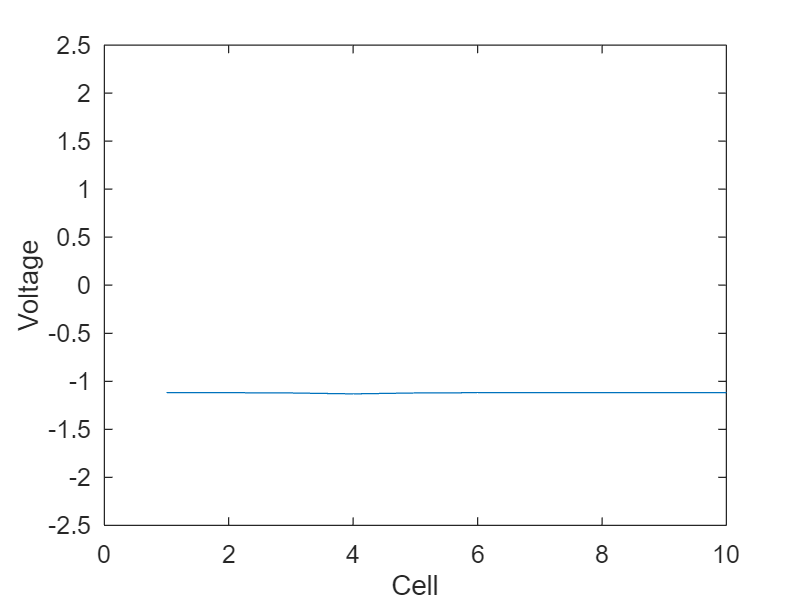


figure(7)
% movie
for nt=1:numel(T)
    figure(5); clf; hold on; box on;
    plot(X(nt,1:10)); 
    set(gca,'ylim', [-2.5,2.5])
    xlabel('Cell');
    ylabel('Voltage')
    drawnow;
end